# **Calculation of Number of Sites Based on Capacity**

## To Get Number of Sites Required to Cover a Certain Area:

## First Step : Calculate Site Capacity.

## 
$$\begin{array}{l}
T_{\textrm{cell}} ={10}^{-6} \times \textrm{No}\ldotp \textrm{of}\;\textrm{carriers}\times \textrm{No}\ldotp \textrm{of}\;\textrm{layers}\times \textrm{Scaling}\;\textrm{Factor}\times \textrm{No}\ldotp \textrm{of}\;\textrm{RBs}\;\textrm{in}\;\sec \times \textrm{No}\ldotp \textrm{of}\;\textrm{REs}\;\textrm{per}\;\textrm{RB}\times \\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\textrm{No}\ldotp \textrm{of}\;\textrm{bits}\;\textrm{per}\;\textrm{RE}\times \textrm{Coding}\;\textrm{Rate}\times \left(1-\textrm{OH}\right)
\end{array}$$


## For FDD mode.

##                 
$$T_{\textrm{site}} =T_{\textrm{cell}} \times \left(\textrm{No}\ldotp \textrm{of}\;\textrm{cells}/\textrm{site}\right)\times Q$$


## For TDD mode.

##                 
$$T_{\textrm{site}} =T_{\textrm{cell}} \times \textrm{DL}\;\textrm{ratio}\times \left(\textrm{No}\ldotp \textrm{of}\;\textrm{cells}/\textrm{site}\right)\times Q$$


### Where:

####             $T_{\textrm{site}}$**:actual site throughput.**

####             $T_{\textrm{cell}}$**:actual cell throughput.**

####             $Q$** :System load.**

## Second Step : Calculate Total Area Traffic.

## 
$$\textrm{Total}\;\textrm{Area}\;\textrm{Traffic}=\textrm{No}\ldotp \textrm{of}\;\textrm{Active}\;\textrm{Users}\times \textrm{Traffic}\;\textrm{per}\;\textrm{User}$$


### 
$$\textrm{No}\ldotp \textrm{of}\;\textrm{Active}\;\textrm{Users}\;=\;\textrm{Total}\;\textrm{Population}\times \textrm{Mobile}\;\textrm{Penetration}\times \textrm{Operator}\;\textrm{Market}\;\textrm{Share}\times \textrm{BHAU}$$


### 
$$\textrm{Traffic}\;\textrm{per}\;\textrm{User}\;=\sum \textrm{BHSA}\;\times \textrm{Service}\;\textrm{Penetration}\;\times \textrm{Session}\;\textrm{Traffic}$$


## Last Step : Divide Total Area Traffic By Site Capacity to Get Number of Sites.

## 
$$\textrm{No}\ldotp \textrm{of}\;\textrm{Sites}=\textrm{Total}\;\textrm{Area}\;\textrm{Traffic}\;/\;\textrm{Site}\;\textrm{Capacity}$$


# **Calculations:**

# **1- Site Capacity Calculation :**

TDD_FDD="tdd";
DL_UL="DL";
DL_ratio=0.8;

FR="FR1";

if FR=="FR1"
    scs_lst=["15KHz","30KHz","60KHz"];
else
    scs_lst=["60KHz","120KHz"];
end
SCS=scs_lst(2);
if SCS=="15KHz"
    SCS_index=1;
elseif SCS=="30KHz"
    SCS_index=2;
elseif SCS=="60KHz"
    SCS_index=3;
elseif SCS=="120KHz"
    SCS_index=4;
end

if FR=="FR1"
    bw_lst=["5MHz","10MHz","15MHz","20MHz","25MHz","30MHz","40MHz","50MHz","60MHz","80MHz","90MHz","100MHz"];

else
    bw_lst=["50MHz","100MHz","200MHz","400MHz"];
end
BW=bw_lst(10);
BW_index=find(contains(bw_lst,BW),1);

if SCS=="60KHz"
    cp_lst=["normal","extended"];
else
    cp_lst="normal";
end
cycle_prefix=cp_lst(1);


## 1-Cell Traffic :

## 
$$\begin{array}{l}
T_{\textrm{cell}} ={10}^{-6} \times \textrm{No}\ldotp \textrm{of}\;\textrm{carriers}\times \textrm{No}\ldotp \textrm{of}\;\textrm{layers}\times \textrm{Scaling}\;\textrm{Factor}\times \textrm{No}\ldotp \textrm{of}\;\textrm{RBs}\;\textrm{in}\;\sec \times \textrm{No}\ldotp \textrm{of}\;\textrm{REs}\;\textrm{per}\;\textrm{RB}\times \\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\textrm{No}\ldotp \textrm{of}\;\textrm{bits}\;\textrm{per}\;\textrm{RE}\times \textrm{Coding}\;\textrm{Rate}\times \left(1-\textrm{OH}\right)
\end{array}$$


No_of_carriers=1;
No_of_layers=4;

if TDD_FDD=="tdd"
    Scaling_factor=0.8;
else
    Scaling_factor=1;
end
disp("Scaling Factor ="+Scaling_factor)

Scaling Factor =0.8


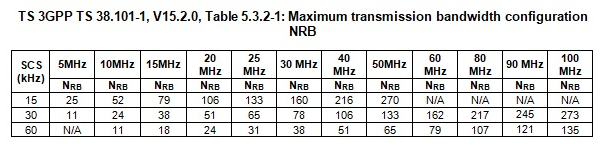

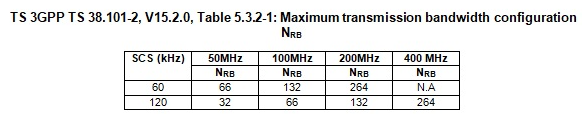

NRB_FR1=[25 52 79 106 133 160 216 270 nan nan nan nan;
        11 24 38 51 65 78 106 133 162 217 245 273;
        nan 11 18 24 31 38 51 65 79 107 121 135];
NRB_FR2=[66 132 264 nan;
        32 66 132 264];


if FR=="FR1"
    if DL_UL=="DL"
        OH=0.14;
    else
        OH=0.08;
    end
    number_of_RBs=NRB_FR1(SCS_index,BW_index);
else
    if DL_UL=="DL"
        OH=0.18;
    else
        OH=0.10;
    end
    number_of_RBs=NRB_FR2(SCS_index-2,BW_index);
end
number_of_slots_per_second=2^(SCS_index-1)*(1000);
No_of_RBsinsec=number_of_RBs*number_of_slots_per_second;


disp("Number of RBs ="+number_of_RBs)

Number of RBs =217


disp("Number of RBs in Second ="+No_of_RBsinsec)

Number of RBs in Second =434000


disp("Control Channel Percentage (Over Head) ="+OH)

Control Channel Percentage (Over Head) =0.14


if cycle_prefix=="normal"
    No_of_REsperRB = 12 * 14;
elseif cycle_prefix=="extended"
    No_of_REsperRB = 12 * 12;
end
disp("Number of REs per RB ="+No_of_REsperRB)

Number of REs per RB =168


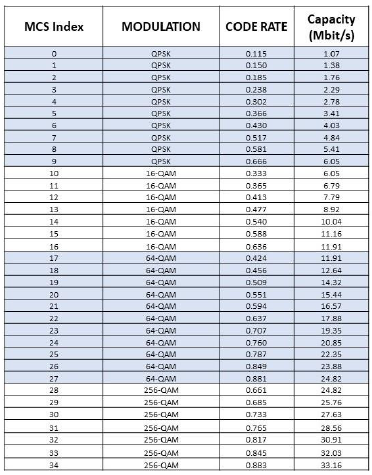

modu_tec="64QAM";

if modu_tec=="Qpsk"
    No_of_bits_per_symbol=2;
elseif modu_tec=="16QAM"
    No_of_bits_per_symbol=4;
elseif modu_tec=="64QAM"
    No_of_bits_per_symbol=6;
elseif modu_tec=="256QAM"
    No_of_bits_per_symbol=8;
end
disp("Maximum modulation order ="+No_of_bits_per_symbol)

Maximum modulation order =6



Code_Rate_QPSK=[0.115 0.15 0.185 0.238 0.302 0.366 0.430 0.517 0.581 0.666];
Code_Rate_16QAM=[0.333 0.365 0.413 0.477 0.540 0.588 0.636];
Code_Rate_64QAM=[0.424 0.456 0.509 0.551 0.594 0.637 0.707 0.76 0.787 0.849 0.881];
Code_Rate_256QAM=[0.661 0.685 0.733 0.765 0.817 0.845 0.883];

if modu_tec=="Qpsk"
    R_max=max(Code_Rate_QPSK);
elseif modu_tec=="16QAM"
    R_max=max(Code_Rate_16QAM);
elseif modu_tec=="64QAM"
    R_max=max(Code_Rate_64QAM);
elseif modu_tec=="256QAM"
    R_max=max(Code_Rate_256QAM);
end

R_max = R_max + double(false)*(0.9257 - R_max);

disp("Code Rate (Rmax) ="+R_max)

Code Rate (Rmax) =0.881


## 
$$\begin{array}{l}
T_{\textrm{cell}} ={10}^{-6} \times \textrm{No}\ldotp \textrm{of}\;\textrm{carriers}\times \textrm{No}\ldotp \textrm{of}\;\textrm{layers}\times \textrm{Scaling}\;\textrm{Factor}\times \textrm{No}\ldotp \textrm{of}\;\textrm{RBs}\;\textrm{in}\;\sec \times \textrm{No}\ldotp \textrm{of}\;\textrm{REs}\;\textrm{per}\;\textrm{RB}\times \\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\textrm{No}\ldotp \textrm{of}\;\textrm{bits}\;\textrm{per}\;\textrm{RE}\times \textrm{Coding}\;\textrm{Rate}\times \left(1-\textrm{OH}\right)
\end{array}$$


T_cell=(10^-6)*No_of_carriers*No_of_layers*No_of_bits_per_symbol*Scaling_factor*R_max*No_of_RBsinsec*No_of_REsperRB*( 1 - OH);

disp("cell traffic= "+T_cell+"Mbps");

cell traffic= 1060.6561Mbps


## 2-Site Capacity :

Q=0.7;
No_of_cells=3;

if TDD_FDD=="tdd"
    site_capacity=T_cell*No_of_cells*DL_ratio*Q;
else
    site_capacity=T_cell*No_of_cells*Q;
end
disp("Site Capacity "+ site_capacity+"Mbps");

Site Capacity 1781.9023Mbps


# **2- Total Area Traffic Calculation :**

## 1-No of Active Users :

total_population=105000;
Mobile_penetration=1.25;
Operator_market_share=0.35;
BHAU=0.8;
No_of_Active_users = total_population * Mobile_penetration * Operator_market_share * BHAU;

disp("Number of Active Users ="+No_of_Active_users);

Number of Active Users =36750


## 2-Traffic per user :

% ( BHSA) *(Service_penetration )*( session_Traffic )
BLER=0.01;


### for Voice call traffic

voicecall_session_bearer=0.064;
voicecall_Session_time=3.5;
voicecall_session_duty_ratio=0.4;

voicecall_traffic = ( voicecall_session_bearer ) * ( voicecall_Session_time ) *60* ( voicecall_session_duty_ratio ) / ( 1-BLER );
disp("Voice Traffic ="+voicecall_traffic+"Mbps")

Voice Traffic =5.4303Mbps



voice_penetration=0.25;
voice_BHSA=1;
voice_traffic_per_user=voicecall_traffic*voice_penetration*voice_BHSA;
disp("Voice Traffic per User ="+voice_traffic_per_user+"Mbps")

Voice Traffic per User =1.3576Mbps


### for Browsing traffic 

browsing_session_bearer=1;
browsing_Session_time=60;
browsing_session_duty_ratio=0.1;

browsing_traffic = ( browsing_session_bearer ) * ( browsing_Session_time ) *60* ( browsing_session_duty_ratio ) / ( 1-BLER );
disp("Browsing Traffic ="+browsing_traffic+"Mbps")

Browsing Traffic =363.6364Mbps



browsing_penetration=0.45;
browsing_BHSA=1;
browsing_traffic_per_user=browsing_traffic*browsing_penetration*browsing_BHSA;
disp("Browsing Traffic per User ="+browsing_traffic_per_user+"Mbps")

Browsing Traffic per User =163.6364Mbps


### for Streaming traffic

streaming_session_bearer=4;
streaming_Session_time=30;
streaming_session_duty_ratio=0.2;

streaming_traffic = ( streaming_session_bearer ) * ( streaming_Session_time ) *60* ( streaming_session_duty_ratio ) / ( 1-BLER );
disp("Streaming Traffic ="+streaming_traffic+"Mbps")

Streaming Traffic =1454.5455Mbps



streaming_penetration=0.2;
streaming_BHSA=1;
streaming_traffic_per_user=streaming_traffic*streaming_penetration*streaming_BHSA;
disp("Streaming Traffic per User ="+streaming_traffic_per_user+"Mbps")

Streaming Traffic per User =290.9091Mbps


### for Gaming traffic

gaming_session_bearer=2;
gaming_Session_time=60;
gaming_session_duty_ratio=0.5;

gaming_traffic = ( gaming_session_bearer ) * ( gaming_Session_time ) *60* ( gaming_session_duty_ratio ) / ( 1-BLER );
disp("gaming Traffic ="+gaming_traffic+"Mbps")

gaming Traffic =3636.3636Mbps



gaming_penetration=0.1;
gaming_BHSA=1;
gaming_traffic_per_user=gaming_traffic*gaming_penetration*gaming_BHSA;
disp("gaming Traffic per User ="+gaming_traffic_per_user+"Mbps")

gaming Traffic per User =363.6364Mbps


traffic_per_user = voice_traffic_per_user + browsing_traffic_per_user + streaming_traffic_per_user + gaming_traffic_per_user;
disp("Traffic per User ="+ traffic_per_user+"Mbps");

Traffic per User =819.5394


total_area_traffic=  No_of_Active_users * traffic_per_user/(3600);
disp("Area Traffic ="+ total_area_traffic+"Mbps");

Area Traffic =8366.1313


# **Number Of Sites Based on Capacity:**

## 
$$\textrm{No}\ldotp \textrm{of}\;\textrm{Sites}=\textrm{Total}\;\textrm{Area}\;\textrm{Traffic}\;/\;\textrm{Site}\;\textrm{Capacity}$$


No_of_site = total_area_traffic / site_capacity;
disp("Total Number of Sites = " +No_of_site);

Total Number of Sites = 4.6951


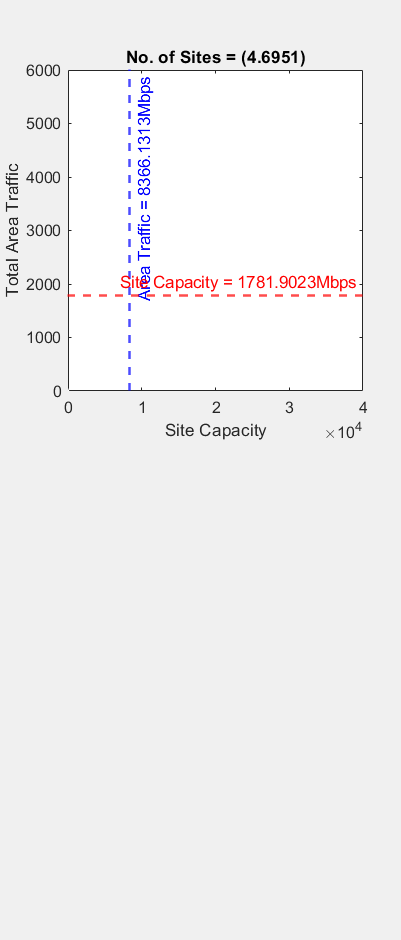

p_x=1:3*round(site_capacity);
p_y=1:3*round(site_capacity);
for i=p_x
    p_y(i)=No_of_site*i;
end
if exist("f","var") && isvalid(f)
    set(0,"CurrentFigure",f);
else
    f=figure("Name","No. of Sites Based on Capacity","Visible","on","WindowStyle","docked",'NumberTitle','off');
end
subplot(2,1,1);
plot(p_y,p_x,"w","LineWidth",1);
ylabel("Total Area Traffic");
xlabel("Site Capacity");
title("No. of Sites = ("+No_of_site+")");
xlim([0 4e4]);
% ylim([50 160]);
xline(total_area_traffic,'--b',"Area Traffic = "+string(total_area_traffic)+"Mbps","LineWidth",1.5);
yline(site_capacity,'--r',"Site Capacity = "+string(site_capacity)+"Mbps","LineWidth",1.5);

#### Other Important Links for Capacity Throughput Calculations:

- [https://www.5g-networks.net/5g-technology/5g-capacity-throughput-calculation/](https://www.5g-networks.net/5g-technology/5g-capacity-throughput-calculation/)

- [https://www.rfwireless-world.com/calculators/5G-NR-maximum-throughput-calculator.html](https://www.rfwireless-world.com/calculators/5G-NR-maximum-throughput-calculator.html)

- [https://5g-tools.com/5g-nr-throughput-calculator/](https://5g-tools.com/5g-nr-throughput-calculator/)